## L6: Analiza mowy w dziedzinie czasu

Proszę zaimplementować brakujące funkcje (label, pitchwin) tak, aby ostatecznie uzyskać segmentację sygnału na ciszę, fragmenty dźwięczne i bezdźwięczne. Wszystkie funkcje proszę zaimplementować na końcu dostarczonego notatnika

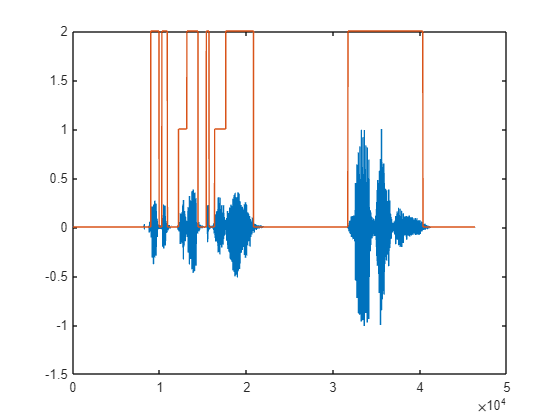

[x, fs] = audioread("percepcja.wav");
x = x / max(x);

lbls = label(x, fs);
plot(x);
hold on;
plot(lbls);

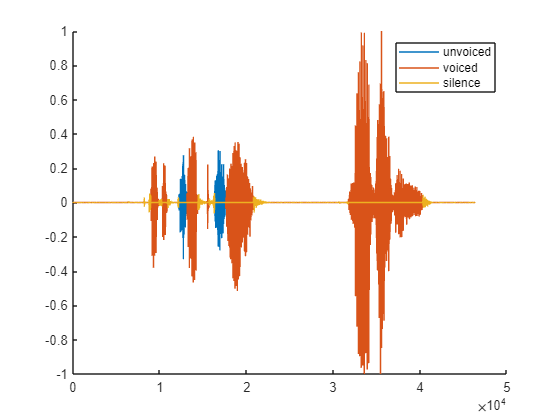

f0 = pitchwin(x, fs, round(fs * 0.1));
f0(lbls ~= 2) = 0;

silence = x;
silence(lbls ~= 0) = 0;

unvoiced = x;
unvoiced(lbls ~= 1) = 0;

voiced = x;
voiced(lbls ~= 2) = 0;

figure;
hold on;
plot(unvoiced);
plot(voiced);
plot(silence);
ylim([-1, 1]);
legend("unvoiced", "voiced", "silence");


%figure;
%plot(f0);

function [lbls] = label(x, fs)

NOT_NOISED_MEAN = 0.5;
STR_THRESHOLD = 0.06;
STE_THRESHOLD = 0.05;
SOUNDNESS_THRESHOLD = 0.5;
% długość okna analizy: 20 ms
win_len = round(fs * 0.02);

% inicjacja lbls
lbls = zeros(length(x),1);

% obliczanie czy sygnał jest w danym momencie dźwięczny czy nie
ste = conv(x.^2, ones(1,win_len), 'same');
ste = ste / max(ste);
str = sqrt(ste);

lbls_active = 1 * (str > STR_THRESHOLD);

for i=1:ceil(length(x)/win_len)
    if i*win_len > length(x)
        endpoint = length(x);
    else
        endpoint = i*win_len;
    end

    win = x(win_len*(i-1)+1:endpoint);

    if mean(lbls_active(win_len*(i-1)+1: endpoint)) > NOT_NOISED_MEAN
        zcr = zerocrossrate(win);
        if zcr > SOUNDNESS_THRESHOLD
            lbls(win_len*(i-1)+1: endpoint) = 1;
        else
            lbls(win_len*(i-1)+1: endpoint) = 2;
        end
    else
        lbls(win_len*(i-1)+1: endpoint) = 0;
    end

end
end

function [x_p] = pitchwin(x, fs, win)
    x_p = x;
end

function zcr = zerocrossrate(x)
    zc = diff(sign(x));
    zcr = sum(zc ~= 0) / length(x);
end